# Dynamics of the three link bipedal robot

## run kinematics firstly

clear
run('Bipedal_kinematics.mlx')

syms ddq1 ddq2 ddq3
syms m1 m2 m3 g

% compute energy
T1 = 1/2 * m1 * (dx1 * dx1 + dz1 * dz1)

$$T1 = \frac{m_{1}\,\left(\frac{{{\mathrm{dq}}_{1}}^{2}\,{l_{1}}^{2}\,{\cos\left(q_{1}\right)}^{2}}{4}+\frac{{{\mathrm{dq}}_{1}}^{2}\,{l_{1}}^{2}\,{\sin\left(q_{1}\right)}^{2}}{4}\right)}{2}$$

T2 = 1/2 * m2 * (dx2 * dx2 + dz2 * dz2)

$$T2 = \frac{m_{2}\,\left({\left({\mathrm{dq}}_{1}\,l_{1}\,\cos\left(q_{1}\right)-\frac{{\mathrm{dq}}_{2}\,l_{2}\,\cos\left(q_{2}\right)}{2}\right)}^{2}+{\left({\mathrm{dq}}_{1}\,l_{1}\,\sin\left(q_{1}\right)-\frac{{\mathrm{dq}}_{2}\,l_{2}\,\sin\left(q_{2}\right)}{2}\right)}^{2}\right)}{2}$$

T3 = 1/2 * m3 * (dx3 * dx3 + dz3 * dz3)

$$T3 = \frac{m_{3}\,\left({\left({\mathrm{dq}}_{1}\,l_{1}\,\cos\left(q_{1}\right)+\frac{{\mathrm{dq}}_{3}\,l_{3}\,\cos\left(q_{3}\right)}{2}\right)}^{2}+{\left({\mathrm{dq}}_{1}\,l_{1}\,\sin\left(q_{1}\right)+\frac{{\mathrm{dq}}_{3}\,l_{3}\,\sin\left(q_{3}\right)}{2}\right)}^{2}\right)}{2}$$


V1 = m1 * g * z1

$$V1 = \frac{g\,l_{1}\,m_{1}\,\cos\left(q_{1}\right)}{2}$$

V2 = m2 * g * z2

$$V2 = g\,m_{2}\,\left(l_{1}\,\cos\left(q_{1}\right)-\frac{l_{2}\,\cos\left(q_{2}\right)}{2}\right)$$

V3 = m3 * g * z3

$$V3 = g\,m_{3}\,\left(l_{1}\,\cos\left(q_{1}\right)+\frac{l_{3}\,\cos\left(q_{3}\right)}{2}\right)$$


T = T1 + T2 + T3

$$T = \begin{array}{l} \frac{m_{1}\,\left(\frac{{{\mathrm{dq}}_{1}}^{2}\,{l_{1}}^{2}\,{\cos\left(q_{1}\right)}^{2}}{4}+\frac{{{\mathrm{dq}}_{1}}^{2}\,{l_{1}}^{2}\,{\sin\left(q_{1}\right)}^{2}}{4}\right)}{2}+\frac{m_{2}\,\left({\left(\sigma_{2}-\frac{{\mathrm{dq}}_{2}\,l_{2}\,\cos\left(q_{2}\right)}{2}\right)}^{2}+{\left(\sigma_{1}-\frac{{\mathrm{dq}}_{2}\,l_{2}\,\sin\left(q_{2}\right)}{2}\right)}^{2}\right)}{2}+\frac{m_{3}\,\left({\left(\sigma_{2}+\frac{{\mathrm{dq}}_{3}\,l_{3}\,\cos\left(q_{3}\right)}{2}\right)}^{2}+{\left(\sigma_{1}+\frac{{\mathrm{dq}}_{3}\,l_{3}\,\sin\left(q_{3}\right)}{2}\right)}^{2}\right)}{2}\\ \mathrm{where}\\ \sigma_{1}={\mathrm{dq}}_{1}\,l_{1}\,\sin\left(q_{1}\right)\\ \sigma_{2}={\mathrm{dq}}_{1}\,l_{1}\,\cos\left(q_{1}\right) \end{array}$$

V = V1 + V2 + V3

$$V = g\,m_{2}\,\left(l_{1}\,\cos\left(q_{1}\right)-\frac{l_{2}\,\cos\left(q_{2}\right)}{2}\right)+g\,m_{3}\,\left(l_{1}\,\cos\left(q_{1}\right)+\frac{l_{3}\,\cos\left(q_{3}\right)}{2}\right)+\frac{g\,l_{1}\,m_{1}\,\cos\left(q_{1}\right)}{2}$$


T = simplify(T ,'steps', 50)

$$T = \frac{{{\mathrm{dq}}_{1}}^{2}\,{l_{1}}^{2}\,m_{1}}{8}+\frac{{{\mathrm{dq}}_{1}}^{2}\,{l_{1}}^{2}\,m_{2}}{2}+\frac{{{\mathrm{dq}}_{1}}^{2}\,{l_{1}}^{2}\,m_{3}}{2}+\frac{{{\mathrm{dq}}_{2}}^{2}\,{l_{2}}^{2}\,m_{2}}{8}+\frac{{{\mathrm{dq}}_{3}}^{2}\,{l_{3}}^{2}\,m_{3}}{8}-\frac{{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{2}\,l_{1}\,l_{2}\,m_{2}\,\cos\left(q_{1}-q_{2}\right)}{2}+\frac{{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{3}\,l_{1}\,l_{3}\,m_{3}\,\cos\left(q_{1}-q_{3}\right)}{2}$$

V = simplify(V, 'steps', 50)

$$V = g\,m_{2}\,\left(l_{1}\,\cos\left(q_{1}\right)-\frac{l_{2}\,\cos\left(q_{2}\right)}{2}\right)+g\,m_{3}\,\left(l_{1}\,\cos\left(q_{1}\right)+\frac{l_{3}\,\cos\left(q_{3}\right)}{2}\right)+\frac{g\,l_{1}\,m_{1}\,\cos\left(q_{1}\right)}{2}$$


if exist('.\Dynamics\eval_T_tmp.m', 'file') == 0
    matlabFunction(T, 'File', '.\Dynamics\eval_T_tmp')
    matlabFunction(V, 'File', '.\Dynamics\eval_V_tmp')
end
% Lagrangian
L = T  - V

$$L = \frac{{{\mathrm{dq}}_{1}}^{2}\,{l_{1}}^{2}\,m_{1}}{8}+\frac{{{\mathrm{dq}}_{1}}^{2}\,{l_{1}}^{2}\,m_{2}}{2}+\frac{{{\mathrm{dq}}_{1}}^{2}\,{l_{1}}^{2}\,m_{3}}{2}+\frac{{{\mathrm{dq}}_{2}}^{2}\,{l_{2}}^{2}\,m_{2}}{8}+\frac{{{\mathrm{dq}}_{3}}^{2}\,{l_{3}}^{2}\,m_{3}}{8}-g\,m_{2}\,\left(l_{1}\,\cos\left(q_{1}\right)-\frac{l_{2}\,\cos\left(q_{2}\right)}{2}\right)-g\,m_{3}\,\left(l_{1}\,\cos\left(q_{1}\right)+\frac{l_{3}\,\cos\left(q_{3}\right)}{2}\right)-\frac{g\,l_{1}\,m_{1}\,\cos\left(q_{1}\right)}{2}-\frac{{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{2}\,l_{1}\,l_{2}\,m_{2}\,\cos\left(q_{1}-q_{2}\right)}{2}+\frac{{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{3}\,l_{1}\,l_{3}\,m_{3}\,\cos\left(q_{1}-q_{3}\right)}{2}$$


% derivatives
dLdq1 = diff(L, q1)

$$dLdq1 = \frac{g\,l_{1}\,m_{1}\,\sin\left(q_{1}\right)}{2}+g\,l_{1}\,m_{2}\,\sin\left(q_{1}\right)+g\,l_{1}\,m_{3}\,\sin\left(q_{1}\right)+\frac{{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{2}\,l_{1}\,l_{2}\,m_{2}\,\sin\left(q_{1}-q_{2}\right)}{2}-\frac{{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{3}\,l_{1}\,l_{3}\,m_{3}\,\sin\left(q_{1}-q_{3}\right)}{2}$$

dLdq2 = diff(L, q2)

$$dLdq2 = -\frac{g\,l_{2}\,m_{2}\,\sin\left(q_{2}\right)}{2}-\frac{{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{2}\,l_{1}\,l_{2}\,m_{2}\,\sin\left(q_{1}-q_{2}\right)}{2}$$

dLdq3 = diff(L, q3)

$$dLdq3 = \frac{g\,l_{3}\,m_{3}\,\sin\left(q_{3}\right)}{2}+\frac{{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{3}\,l_{1}\,l_{3}\,m_{3}\,\sin\left(q_{1}-q_{3}\right)}{2}$$


dLddq1 = diff(L, dq1)

$$dLddq1 = \frac{{\mathrm{dq}}_{1}\,{l_{1}}^{2}\,m_{1}}{4}+{\mathrm{dq}}_{1}\,{l_{1}}^{2}\,m_{2}+{\mathrm{dq}}_{1}\,{l_{1}}^{2}\,m_{3}-\frac{{\mathrm{dq}}_{2}\,l_{1}\,l_{2}\,m_{2}\,\cos\left(q_{1}-q_{2}\right)}{2}+\frac{{\mathrm{dq}}_{3}\,l_{1}\,l_{3}\,m_{3}\,\cos\left(q_{1}-q_{3}\right)}{2}$$

dLddq2 = diff(L, dq2)

$$dLddq2 = \frac{{\mathrm{dq}}_{2}\,{l_{2}}^{2}\,m_{2}}{4}-\frac{{\mathrm{dq}}_{1}\,l_{1}\,l_{2}\,m_{2}\,\cos\left(q_{1}-q_{2}\right)}{2}$$

dLddq3 = diff(L, dq3)

$$dLddq3 = \frac{{\mathrm{dq}}_{3}\,m_{3}\,{l_{3}}^{2}}{4}+\frac{{\mathrm{dq}}_{1}\,l_{1}\,m_{3}\,\cos\left(q_{1}-q_{3}\right)\,l_{3}}{2}$$


dLddq1_dt = diff(dLddq1, q1) * dq1 + ...
            diff(dLddq1, dq1) * ddq1 + ...
            diff(dLddq1, q2) * dq2 + ...
            diff(dLddq1, dq2) * ddq2 + ...
            diff(dLddq1, q3) * dq3 + ...
            diff(dLddq1, dq3) * ddq3

$$dLddq1\_dt = {\mathrm{dq}}_{1}\,\left(\frac{{\mathrm{dq}}_{2}\,l_{1}\,l_{2}\,m_{2}\,\sin\left(q_{1}-q_{2}\right)}{2}-\frac{{\mathrm{dq}}_{3}\,l_{1}\,l_{3}\,m_{3}\,\sin\left(q_{1}-q_{3}\right)}{2}\right)+{\mathrm{ddq}}_{1}\,\left(\frac{{l_{1}}^{2}\,m_{1}}{4}+{l_{1}}^{2}\,m_{2}+{l_{1}}^{2}\,m_{3}\right)-\frac{{\mathrm{ddq}}_{2}\,l_{1}\,l_{2}\,m_{2}\,\cos\left(q_{1}-q_{2}\right)}{2}+\frac{{\mathrm{ddq}}_{3}\,l_{1}\,l_{3}\,m_{3}\,\cos\left(q_{1}-q_{3}\right)}{2}-\frac{{{\mathrm{dq}}_{2}}^{2}\,l_{1}\,l_{2}\,m_{2}\,\sin\left(q_{1}-q_{2}\right)}{2}+\frac{{{\mathrm{dq}}_{3}}^{2}\,l_{1}\,l_{3}\,m_{3}\,\sin\left(q_{1}-q_{3}\right)}{2}$$


dLddq2_dt = diff(dLddq2, q1) * dq1 + ...
            diff(dLddq2, dq1) * ddq1 + ...
            diff(dLddq2, q2) * dq2 + ...
            diff(dLddq2, dq2) * ddq2 + ...
            diff(dLddq2, q3) * dq3 + ...
            diff(dLddq2, dq3) * ddq3

$$dLddq2\_dt = \frac{l_{1}\,m_{2}\,\sin\left(q_{1}-q_{2}\right)\,{{\mathrm{dq}}_{1}}^{2}\,l_{2}}{2}-\frac{{\mathrm{dq}}_{2}\,l_{1}\,m_{2}\,\sin\left(q_{1}-q_{2}\right)\,{\mathrm{dq}}_{1}\,l_{2}}{2}+\frac{{\mathrm{ddq}}_{2}\,m_{2}\,{l_{2}}^{2}}{4}-\frac{{\mathrm{ddq}}_{1}\,l_{1}\,m_{2}\,\cos\left(q_{1}-q_{2}\right)\,l_{2}}{2}$$


dLddq3_dt = diff(dLddq3, q1) * dq1 + ...
            diff(dLddq3, dq1) * ddq1 + ...
            diff(dLddq3, q2) * dq2 + ...
            diff(dLddq3, dq2) * ddq2 + ...
            diff(dLddq3, q3) * dq3 + ...
            diff(dLddq3, dq3) * ddq3

$$dLddq3\_dt = -\frac{l_{1}\,m_{3}\,\sin\left(q_{1}-q_{3}\right)\,{{\mathrm{dq}}_{1}}^{2}\,l_{3}}{2}+\frac{{\mathrm{dq}}_{3}\,l_{1}\,m_{3}\,\sin\left(q_{1}-q_{3}\right)\,{\mathrm{dq}}_{1}\,l_{3}}{2}+\frac{{\mathrm{ddq}}_{3}\,m_{3}\,{l_{3}}^{2}}{4}+\frac{{\mathrm{ddq}}_{1}\,l_{1}\,m_{3}\,\cos\left(q_{1}-q_{3}\right)\,l_{3}}{2}$$


Eq1 = dLddq1_dt - dLdq1;
Eq2 = dLddq2_dt - dLdq2;
Eq3 = dLddq3_dt - dLdq3;

Eq1 = simplify(Eq1);
Eq2 = simplify(Eq2);
Eq3 = simplify(Eq3);
Eq = simplify(collect([Eq1; Eq2; Eq3], [ddq1, ddq2, ddq3, dq1, dq2, dq3]))

$$Eq = \left(\begin{array}{c} \frac{l_{1}\,\left(l_{1}\,m_{1}+4\,l_{1}\,m_{2}+4\,l_{1}\,m_{3}\right)}{4}\,{\mathrm{ddq}}_{1}+\left(-\frac{l_{1}\,l_{2}\,m_{2}\,\cos\left(q_{1}-q_{2}\right)}{2}\right)\,{\mathrm{ddq}}_{2}+\frac{l_{1}\,l_{3}\,m_{3}\,\cos\left(q_{1}-q_{3}\right)}{2}\,{\mathrm{ddq}}_{3}+\left(-\frac{l_{1}\,l_{2}\,m_{2}\,\sin\left(q_{1}-q_{2}\right)}{2}\right)\,{{\mathrm{dq}}_{2}}^{2}+\frac{l_{1}\,l_{3}\,m_{3}\,\sin\left(q_{1}-q_{3}\right)}{2}\,{{\mathrm{dq}}_{3}}^{2}-\frac{l_{1}\,\left(2\,g\,m_{1}\,\sin\left(q_{1}\right)+4\,g\,m_{2}\,\sin\left(q_{1}\right)+4\,g\,m_{3}\,\sin\left(q_{1}\right)\right)}{4}\\ \frac{l_{2}\,m_{2}\,\left(2\,l_{1}\,\sin\left(q_{1}-q_{2}\right)\,{{\mathrm{dq}}_{1}}^{2}+{\mathrm{ddq}}_{2}\,l_{2}+2\,g\,\sin\left(q_{2}\right)-2\,{\mathrm{ddq}}_{1}\,l_{1}\,\cos\left(q_{1}-q_{2}\right)\right)}{4}\\ \frac{l_{3}\,m_{3}\,\left(-2\,l_{1}\,\sin\left(q_{1}-q_{3}\right)\,{{\mathrm{dq}}_{1}}^{2}+{\mathrm{ddq}}_{3}\,l_{3}-2\,g\,\sin\left(q_{3}\right)+2\,{\mathrm{ddq}}_{1}\,l_{1}\,\cos\left(q_{1}-q_{3}\right)\right)}{4} \end{array}\right)$$

## calculate the M, C, G matrices

G(1, 1) = subs(Eq(1), [ddq1, ddq2, ddq3, dq1, dq2, dq3], [0,0,0,0,0,0]);
G(2, 1) = subs(Eq(2), [ddq1, ddq2, ddq3, dq1, dq2, dq3], [0,0,0,0,0,0]);
G(3, 1) = subs(Eq(3), [ddq1, ddq2, ddq3, dq1, dq2, dq3], [0,0,0,0,0,0]);


M(1, 1) = subs(Eq(1), [ddq1, ddq2, ddq3, dq1, dq2, dq3], [1,0,0,0,0,0]) - G(1, 1);
M(1, 2) = subs(Eq(1), [ddq1, ddq2, ddq3, dq1, dq2, dq3], [0,1,0,0,0,0]) - G(1, 1);
M(1, 3) = subs(Eq(1), [ddq1, ddq2, ddq3, dq1, dq2, dq3], [0,0,1,0,0,0]) - G(1, 1);
M(2, 1) = subs(Eq(2), [ddq1, ddq2, ddq3, dq1, dq2, dq3], [1,0,0,0,0,0]) - G(2, 1);
M(2, 2) = subs(Eq(2), [ddq1, ddq2, ddq3, dq1, dq2, dq3], [0,1,0,0,0,0]) - G(2, 1);
M(2, 3) = subs(Eq(2), [ddq1, ddq2, ddq3, dq1, dq2, dq3], [0,0,1,0,0,0]) - G(2, 1);
M(3, 1) = subs(Eq(3), [ddq1, ddq2, ddq3, dq1, dq2, dq3], [1,0,0,0,0,0]) - G(3, 1);
M(3, 2) = subs(Eq(3), [ddq1, ddq2, ddq3, dq1, dq2, dq3], [0,1,0,0,0,0]) - G(3, 1);
M(3, 3) = subs(Eq(3), [ddq1, ddq2, ddq3, dq1, dq2, dq3], [0,0,1,0,0,0]) - G(3, 1);


C(1, 1) = (subs(Eq(1), [ddq1, ddq2, ddq3, dq1, dq2, dq3], [0,0,0,dq1,0,0]) - G(1, 1)) / dq1;
C(1, 2) = (subs(Eq(1), [ddq1, ddq2, ddq3, dq1, dq2, dq3], [0,0,0,0,dq2,0]) - G(1, 1)) / dq2;
C(1, 3) = (subs(Eq(1), [ddq1, ddq2, ddq3, dq1, dq2, dq3], [0,0,0,0,0,dq3]) - G(1, 1)) / dq3;
C(2, 1) = (subs(Eq(2), [ddq1, ddq2, ddq3, dq1, dq2, dq3], [0,0,0,dq1,0,0]) - G(2, 1)) / dq1;
C(2, 2) = (subs(Eq(2), [ddq1, ddq2, ddq3, dq1, dq2, dq3], [0,0,0,0,dq2,0]) - G(2, 1)) / dq2;
C(2, 3) = (subs(Eq(2), [ddq1, ddq2, ddq3, dq1, dq2, dq3], [0,0,0,0,0,dq3]) - G(2, 1)) / dq3;
C(3, 1) = (subs(Eq(3), [ddq1, ddq2, ddq3, dq1, dq2, dq3], [0,0,0,dq1,0,0]) - G(3, 1)) / dq1;
C(3, 2) = (subs(Eq(3), [ddq1, ddq2, ddq3, dq1, dq2, dq3], [0,0,0,0,dq2,0]) - G(3, 1)) / dq2;
C(3, 3) = (subs(Eq(3), [ddq1, ddq2, ddq3, dq1, dq2, dq3], [0,0,0,0,0,dq3]) - G(3, 1)) / dq3;
G = simplify(G, 'Steps', 50)

$$G = \left(\begin{array}{c} -\frac{g\,l_{1}\,\sin\left(q_{1}\right)\,\left(m_{1}+2\,m_{2}+2\,m_{3}\right)}{2}\\ \frac{g\,l_{2}\,m_{2}\,\sin\left(q_{2}\right)}{2}\\ -\frac{g\,l_{3}\,m_{3}\,\sin\left(q_{3}\right)}{2} \end{array}\right)$$

M = simplify(M, 'Steps', 50)

$$M = \left(\begin{array}{ccc} {l_{1}}^{2}\,\left(\frac{m_{1}}{4}+m_{2}+m_{3}\right) & -\frac{l_{1}\,l_{2}\,m_{2}\,\cos\left(q_{1}-q_{2}\right)}{2} & \frac{l_{1}\,l_{3}\,m_{3}\,\cos\left(q_{1}-q_{3}\right)}{2}\\ -\frac{l_{1}\,l_{2}\,m_{2}\,\cos\left(q_{1}-q_{2}\right)}{2} & \frac{{l_{2}}^{2}\,m_{2}}{4} & 0\\ \frac{l_{1}\,l_{3}\,m_{3}\,\cos\left(q_{1}-q_{3}\right)}{2} & 0 & \frac{{l_{3}}^{2}\,m_{3}}{4} \end{array}\right)$$

C = simplify(C, 'Steps', 50)

$$C = \left(\begin{array}{ccc} 0 & -\frac{{\mathrm{dq}}_{2}\,l_{1}\,l_{2}\,m_{2}\,\sin\left(q_{1}-q_{2}\right)}{2} & \frac{{\mathrm{dq}}_{3}\,l_{1}\,l_{3}\,m_{3}\,\sin\left(q_{1}-q_{3}\right)}{2}\\ \frac{{\mathrm{dq}}_{1}\,l_{1}\,l_{2}\,m_{2}\,\sin\left(q_{1}-q_{2}\right)}{2} & 0 & 0\\ -\frac{{\mathrm{dq}}_{1}\,l_{1}\,l_{3}\,m_{3}\,\sin\left(q_{1}-q_{3}\right)}{2} & 0 & 0 \end{array}\right)$$

## Check a liitle bit

ddq = [ddq1;ddq2;ddq3];
dq = [dq1;dq2;dq3];
Eq = [Eq1;Eq2;Eq3];
error = simplify(M * ddq + C * dq + G - Eq)

$$error = \left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$

## convert symbolic expression into m function

matlabFunction(M, 'File', '.\Dynamics\eval_M_tmp','optimize',1==1)

ans = function_handle with value:
    @eval_M_tmp


matlabFunction(C, 'File', '.\Dynamics\eval_C_tmp','optimize',1==1)

ans = function_handle with value:
    @eval_C_tmp


matlabFunction(G, 'File', '.\Dynamics\eval_G_tmp','optimize',1==1)

ans = function_handle with value:
    @eval_G_tmp


## Calculate B matrix

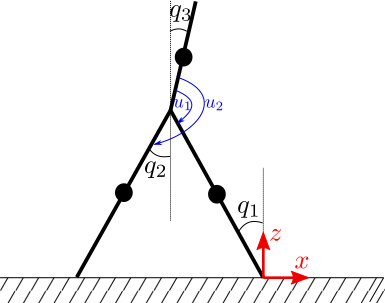

syms u1 u2 delq1 delq2 delq3
th1 = pi + q1 - q3

$$th1 = q_{1}-q_{3}+\pi$$

th2 = pi + q2 - q3

$$th2 = q_{2}-q_{3}+\pi$$


del_th1 = -delq1 - delq3

$$del\_th1 = -{\mathrm{delq}}_{1}-{\mathrm{delq}}_{3}$$

del_th2 = +delq2 - delq3

$$del\_th2 = {\mathrm{delq}}_{2}-{\mathrm{delq}}_{3}$$

del_W1 = u1 * del_th1; % virtual work done by u1
del_W2 = u2 * del_th2; % virtual work done by u2
del_W = del_W1 + del_W2; % total virtual work
del_W = collect(del_W, [delq1, delq2, delq3])

$$del\_W = \left(-u_{1}\right)\,{\mathrm{delq}}_{1}+u_{2}\,{\mathrm{delq}}_{2}+\left(-u_{1}-u_{2}\right)\,{\mathrm{delq}}_{3}$$

R_Eq1 = subs(del_W, {delq1, delq2, delq3}, {1, 0, 0})

$$R\_Eq1 = -u_{1}$$

R_Eq2 = subs(del_W, {delq1, delq2, delq3}, {0, 1, 0})

$$R\_Eq2 = u_{2}$$

R_Eq3 = subs(del_W, {delq1, delq2, delq3}, {0, 0, 1})

$$R\_Eq3 = -u_{1}-u_{2}$$


B(1, 1) = subs(R_Eq1, {u1, u2}, {1, 0});
B(1, 2) = subs(R_Eq1, {u1, u2}, {0, 1});
B(2, 1) = subs(R_Eq2, {u1, u2}, {1, 0});
B(2, 2) = subs(R_Eq2, {u1, u2}, {0, 1});
B(3, 1) = subs(R_Eq3, {u1, u2}, {1, 0});
B(3, 2) = subs(R_Eq3, {u1, u2}, {0, 1})

$$B = \left(\begin{array}{cc} -1 & 0\\ 0 & 1\\ -1 & -1 \end{array}\right)$$

B = sym(B)

$$B = \left(\begin{array}{cc} -1 & 0\\ 0 & 1\\ -1 & -1 \end{array}\right)$$


matlabFunction(B, 'File', '.\Dynamics\eval_B_tmp')

ans = function_handle with value:
    @eval_B_tmp


## tests

addpath('./set_parameters', './dynamics', './test');